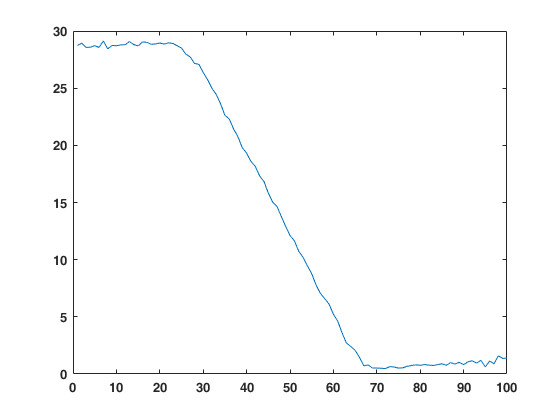

clear; close all; clc;
%% 1
load('ex5.mat')
T = 100;
mu = [mu0];
K = cell([1 T]);
K{1} = L0*B.'/(B*L0*B.' + Gamma);
V = cell([1 T]);
V{1} = (eye(2) -K{1}*B)*L0;

for t = 2:T
    Lt_1 = A*V{t-1}*A.' + Sigma;
    K{t} = Lt_1*B.'/(B*Lt_1*B.' + Gamma);
    V{t} = (eye(2) -K{t}*B)*Lt_1;
    mu1 = A*mu(:,t-1) + C*u(t) + K{t}*(x(:,t)-B*(A*mu(:,t-1) + C*u(t)));
    mu = [mu mu1];
end

%% 2

figure(1)
plot(x(1,:))

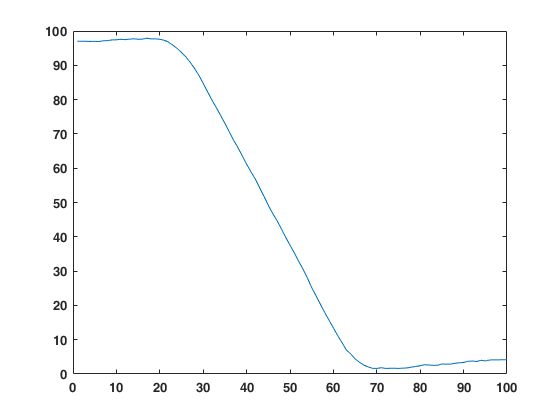

figure(2)
plot(mu(1,:))

From the plot it looks like the drone is flying at 100 meters and then descends to the ground.